clearvars -except kg kg2 rkg k out

# **kg2 fish cleaner**

## multi plotter

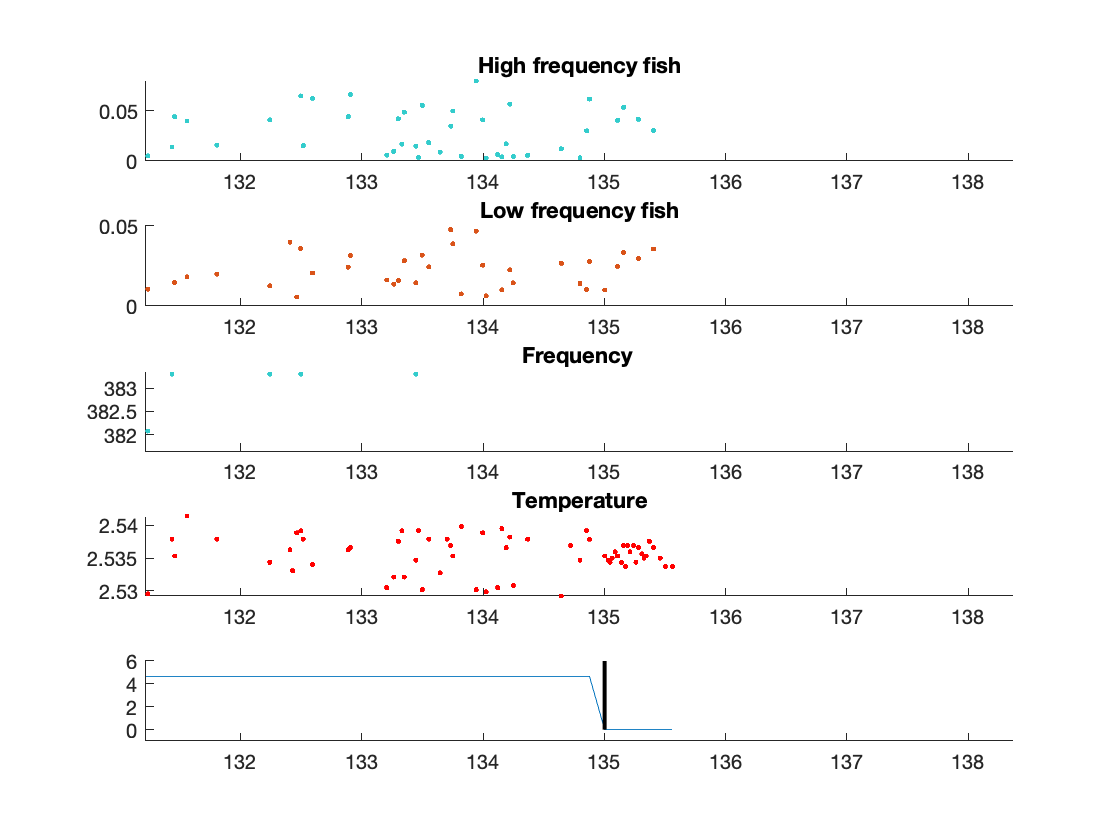

k_multifishplotter(kg2(k));

k = 25;

#### Plot unmodified amplitude data

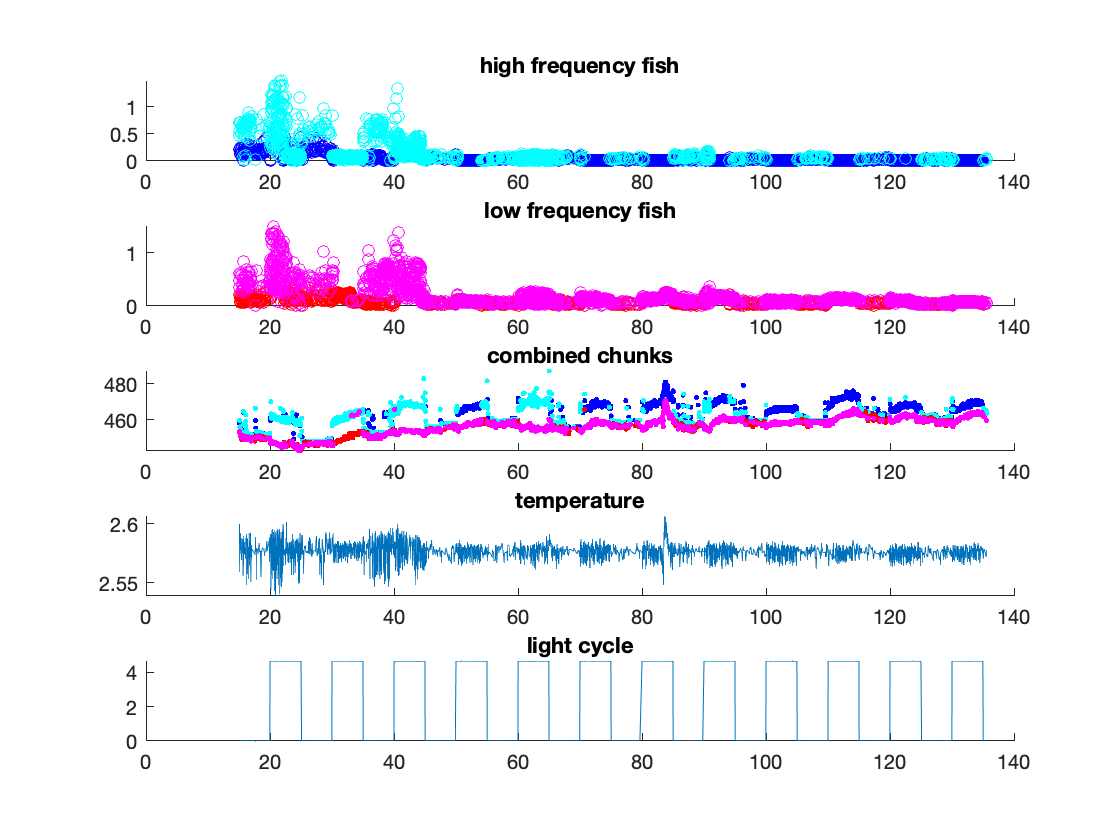

k_peakampmultiplotter(kg2(k).s);

#### trim

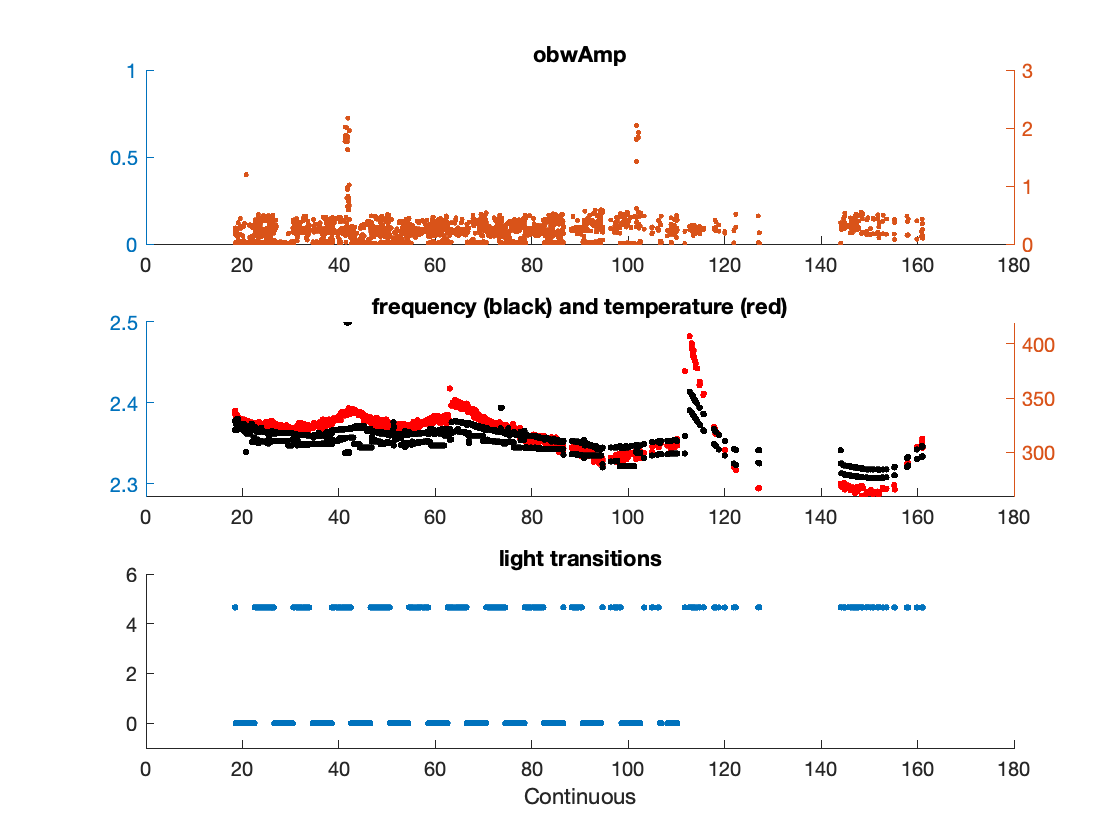

tempdata  = KatieMultiTrimmer(kg2(k).s);

if before was on purpose 

kg2(k).s = tempdata;

#### Filter fish frequency errors

Click cutoff for eliminating erroneously low amplitude measurements.
Click cutoff for eliminating erroneously high amplitude measurements.
Click cutoff for eliminating erroneously low amplitude measurements.
Click cutoff for eliminating erroneously high amplitude measurements.
Click cutoff for eliminating erroneously low amplitude measurements.
Click cutoff for eliminating erroneously high amplitude measurements.
Click cutoff for eliminating erroneously low amplitude measurements.
Click cutoff for eliminating erroneously high amplitude measurements.


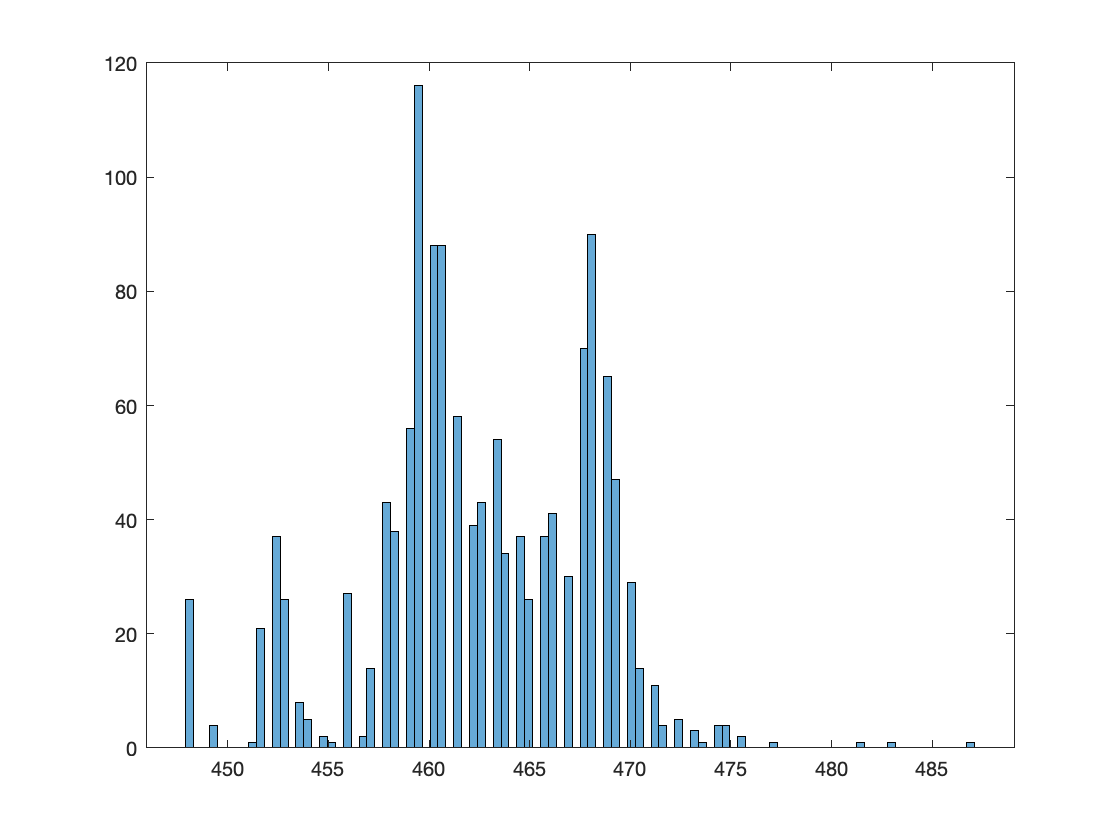

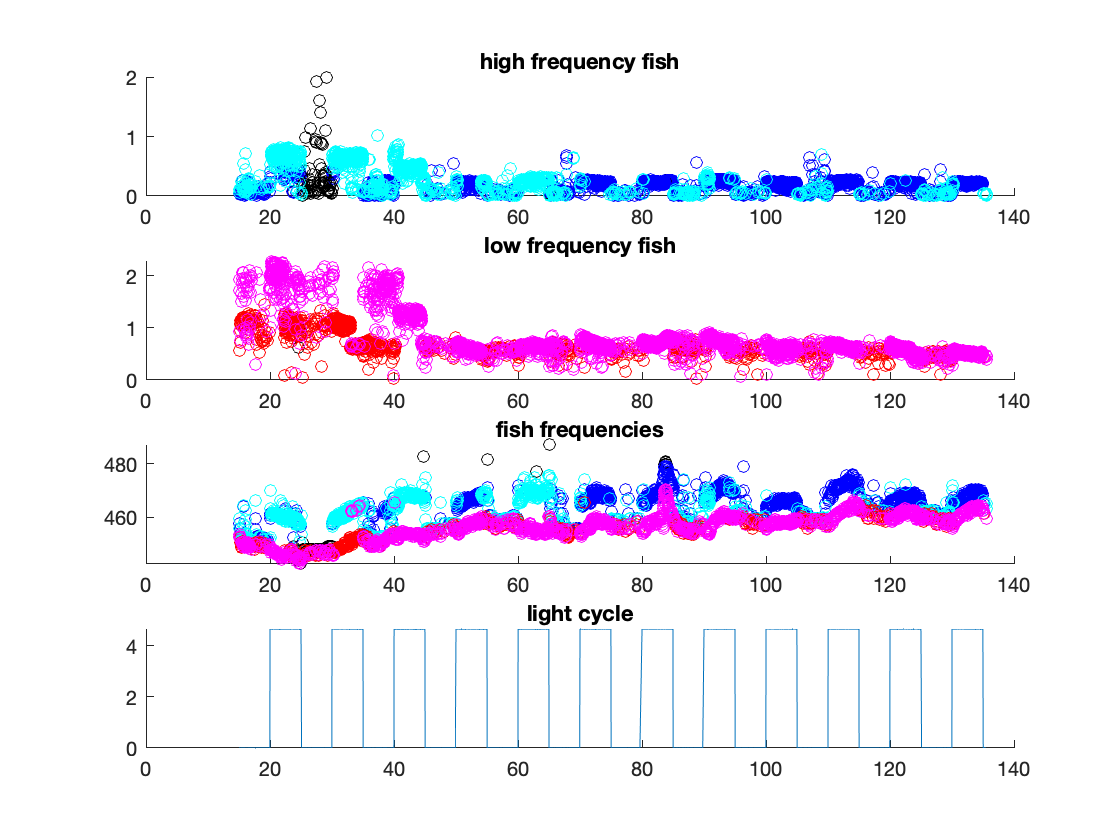

[hi, lo] = k_multifishfreqtrim(kg2(k).s);

hibackup = hi;
lobackup = lo;

for those times we fuck up but don't want to reclick frequency

hi = hibackup;
lo = lobackup;

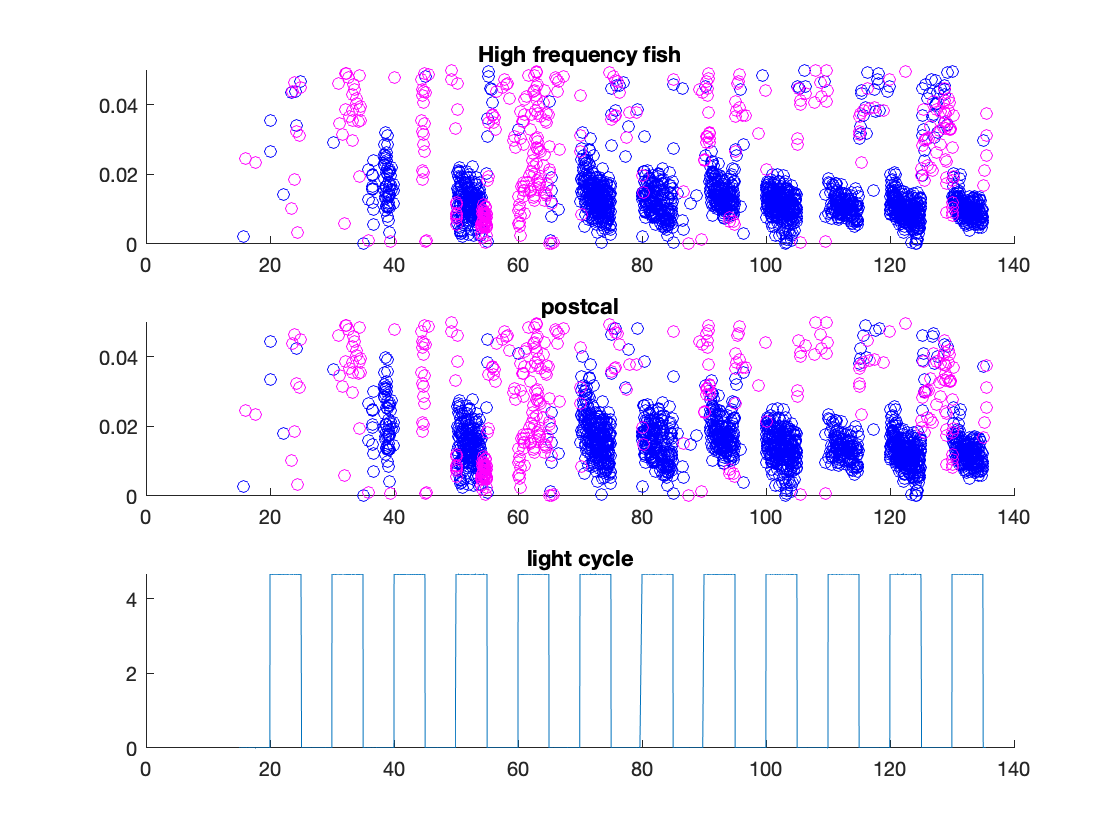

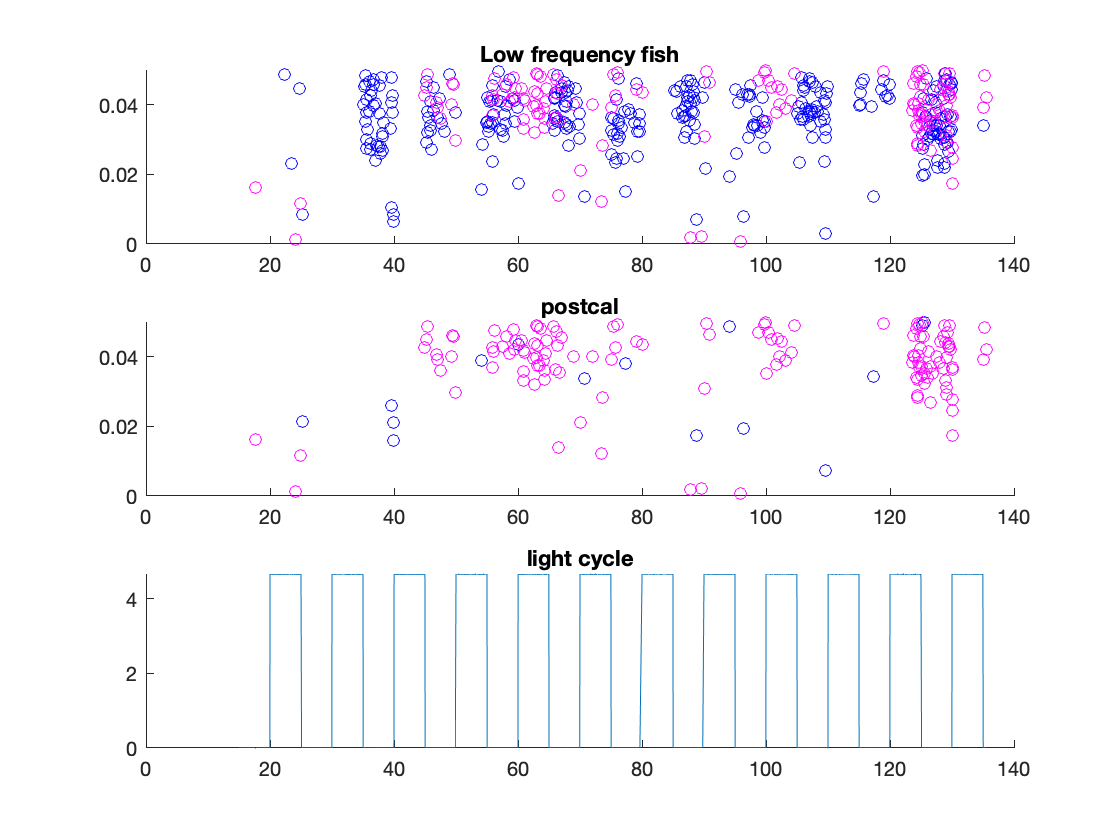

k_fishcalplotter(hi, lo, kg2(k).s);

## Hi frequency fish

tube = 1;

%save calibration
 hi(tube).pkamp = hi(tube).pkamp * 2.2;
 hi(tube).obwamp =  hi(tube).obwamp * 2.2;
 


#### save newly calibrated data into output structure

% sout = KatieFinalfishsplit(in)
kg2(k).hifish = KatieFinalfishsplit(hi);
kg2(k).hical = hi;

%outlier removal
%low amplitude data means fish was not inside tube during recording
kg2(k).hiidx = KatiesingleMultiRemover(kg2(k).hifish);

Click cutoff for eliminating erroneously low amplitude measurements.
Click cutoff for eliminating erroneously high amplitude measurements.
Click cutoff for eliminating erroneously low amplitude measurements.
Click cutoff for eliminating erroneously high amplitude measurements.


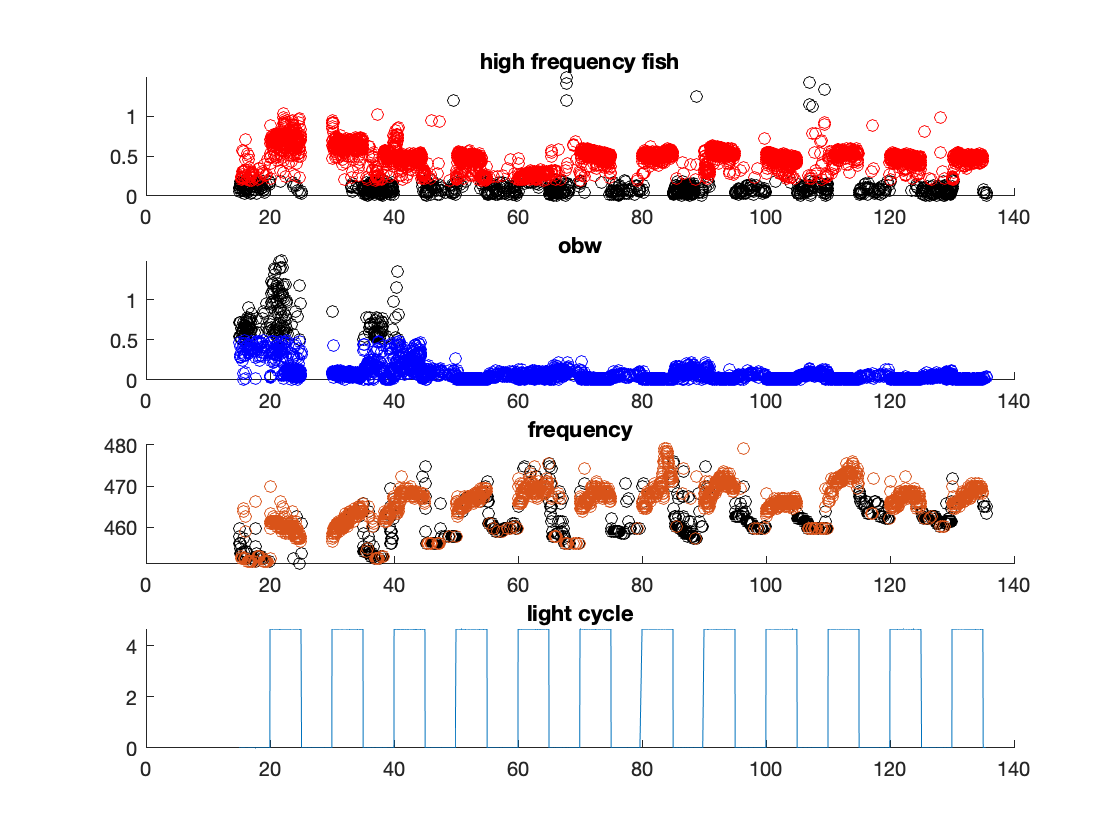

%plot to check
k_removercheckplot(6, kg2(k)); 

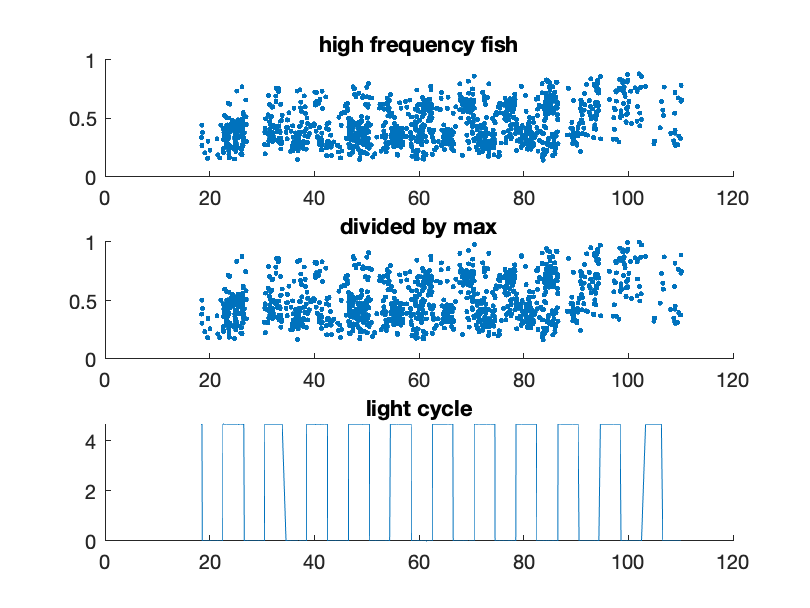

%normalize to max value after removal
kg2(k).himaxval = k_normcheckplot(6, kg2(k));

%mostly just checks 

## Low frequency fish

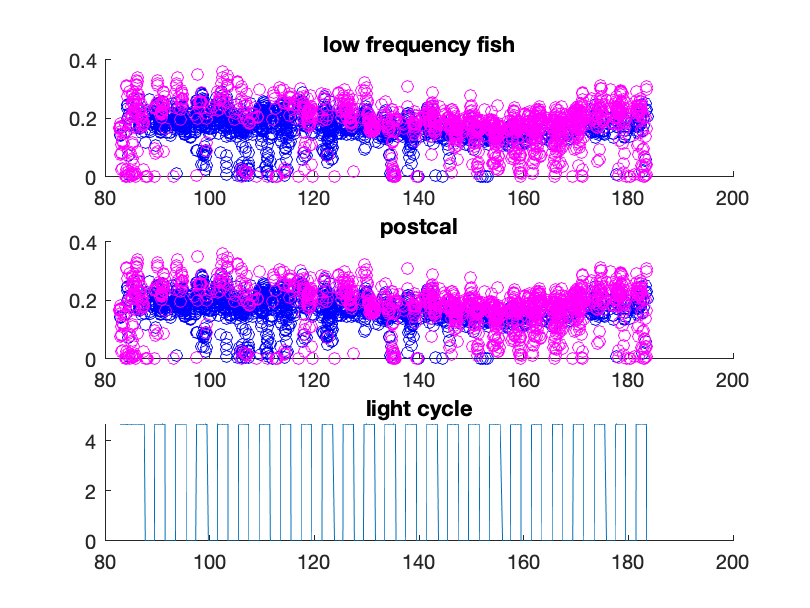

k_fishcalplotter(lo, kg2(k).s, 'low frequency fish');

#### calibrate tubes to eachother

tube = 1;

%save calibration
 lo(tube).pkamp = lo(tube).pkamp * 2.2;
 lo(tube).obwamp =  lo(tube).obwamp * 2.2;


#### Save into output structure

% sout = KatieFinalfishsplit(in)
kg2(k).lofish = KatieFinalfishsplit(lo);
kg2(k).local =  lo;

#### Remove outliers

Click cutoff for eliminating erroneously low amplitude measurements.
Click cutoff for eliminating erroneously high amplitude measurements.
Click cutoff for eliminating erroneously low amplitude measurements.
Click cutoff for eliminating erroneously high amplitude measurements.


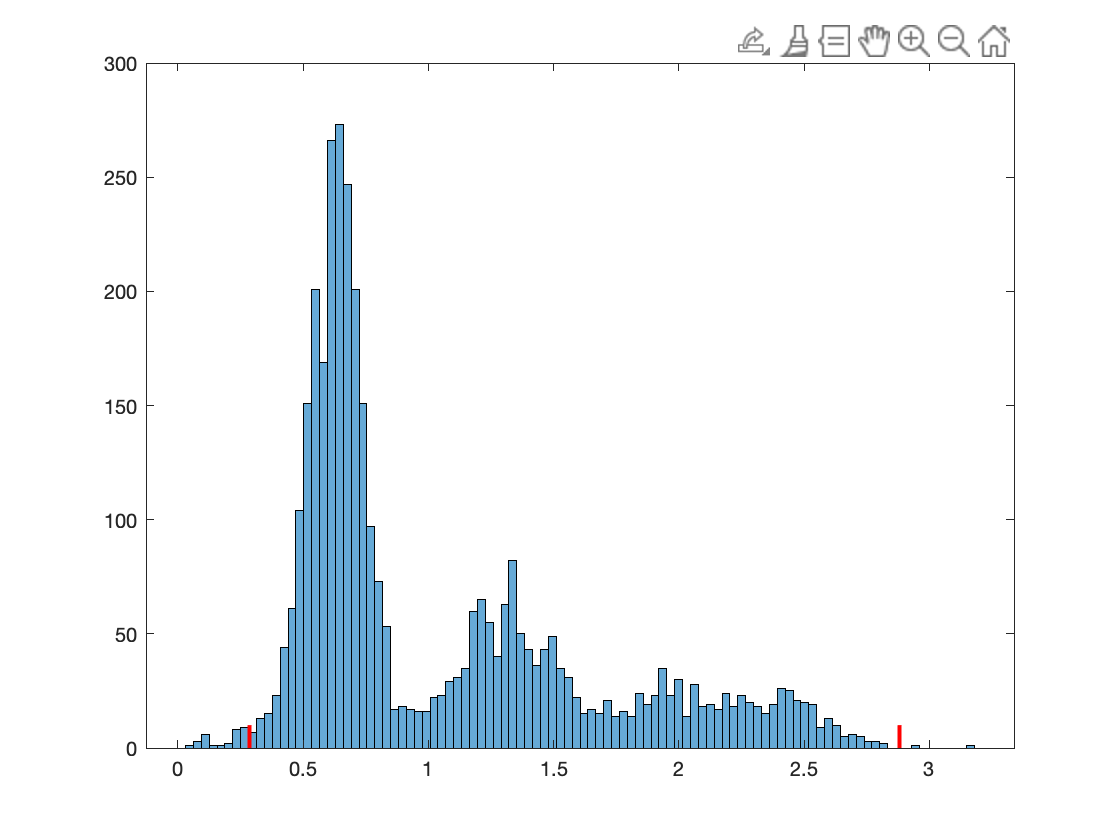

%outlier removal
%low amplitude data means fish was not inside tube during recording
kg2(k).loidx = KatiesingleMultiRemover(kg2(k).lofish);

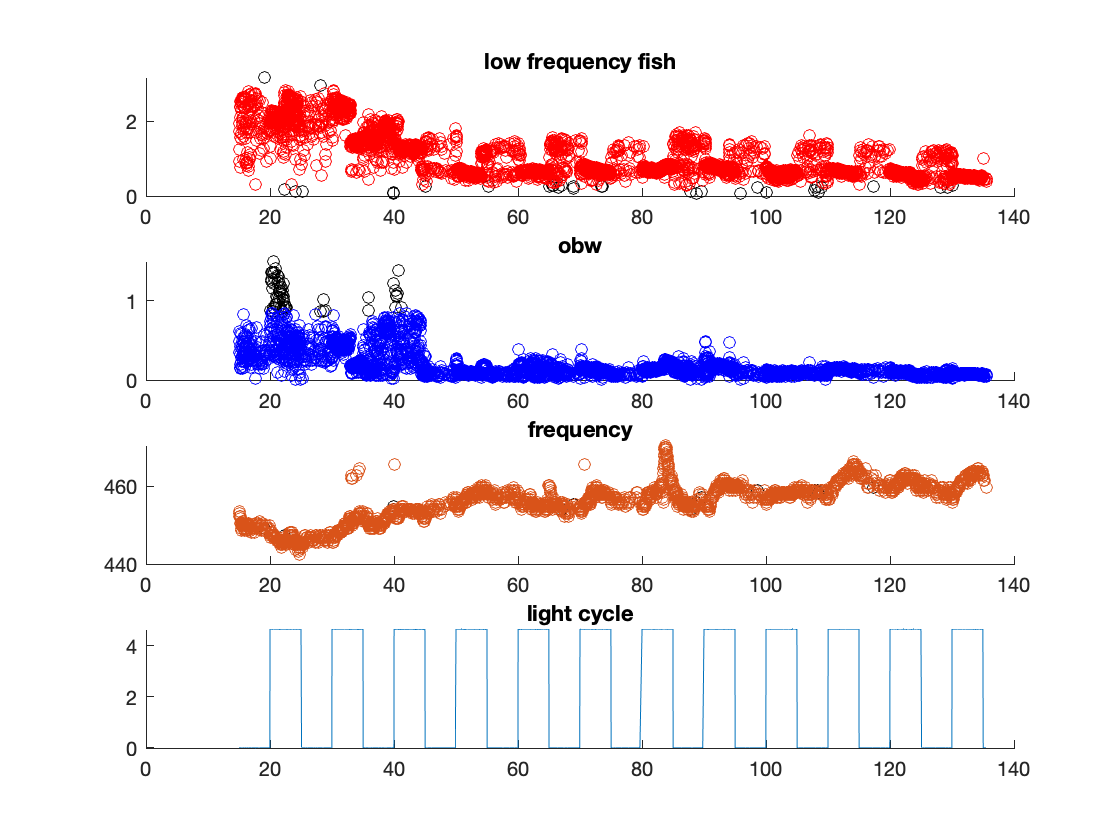

%plot to check
k_removercheckplot(5, kg2(k)); 

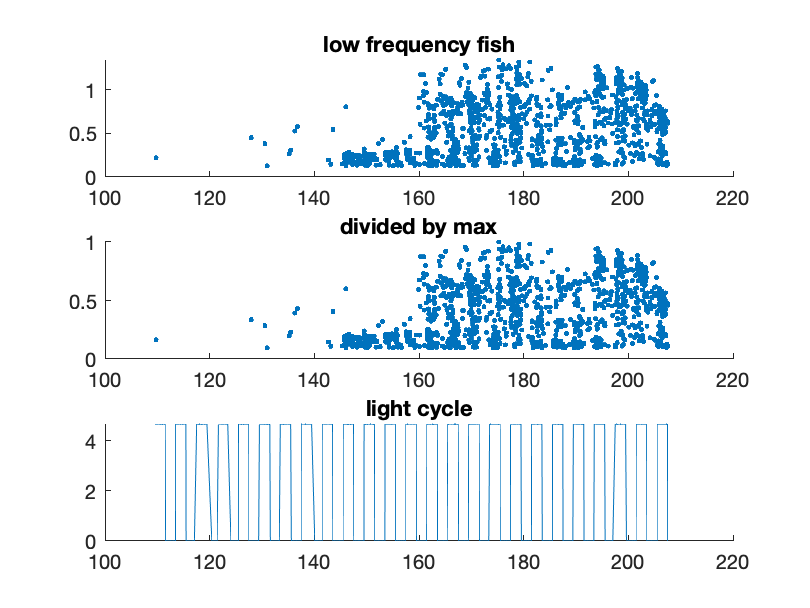

%normalize to max value after removal
kg2(k).lomaxval = k_normcheckplot(5, kg2(k));

%mostly just checks 

## multi plotter

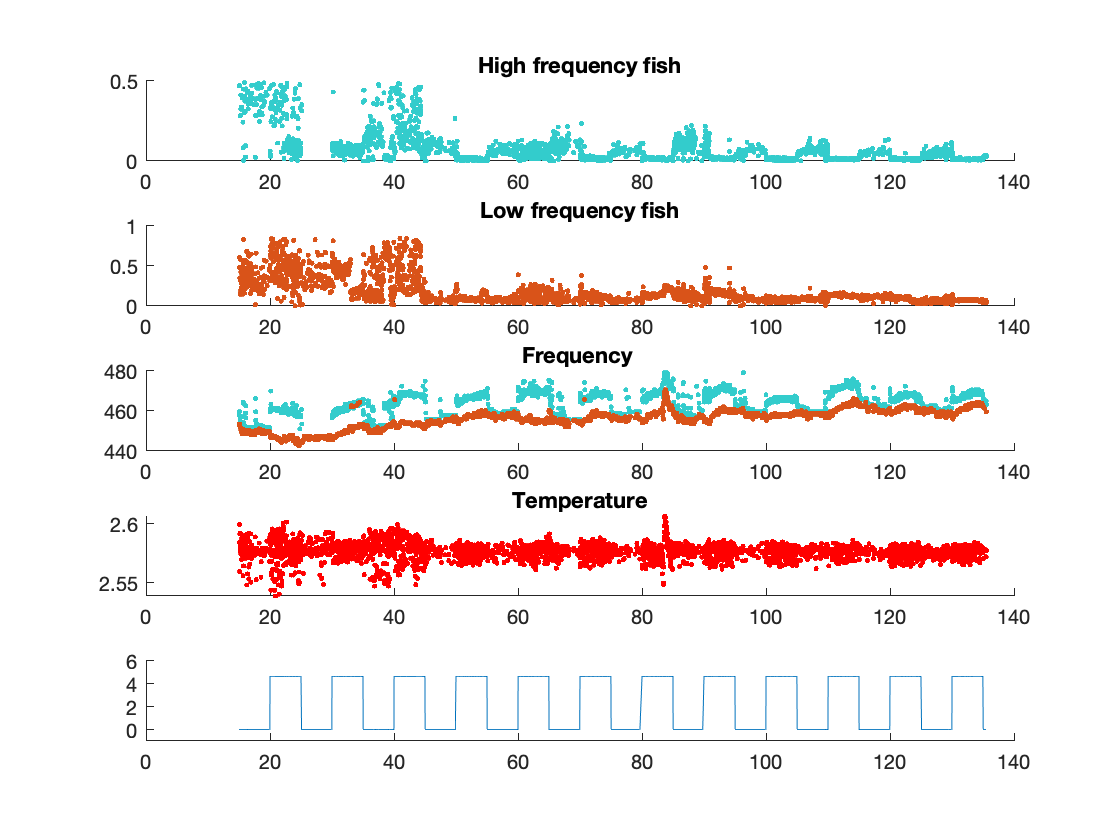

k_multifishplotter(kg2(k));

#### Label

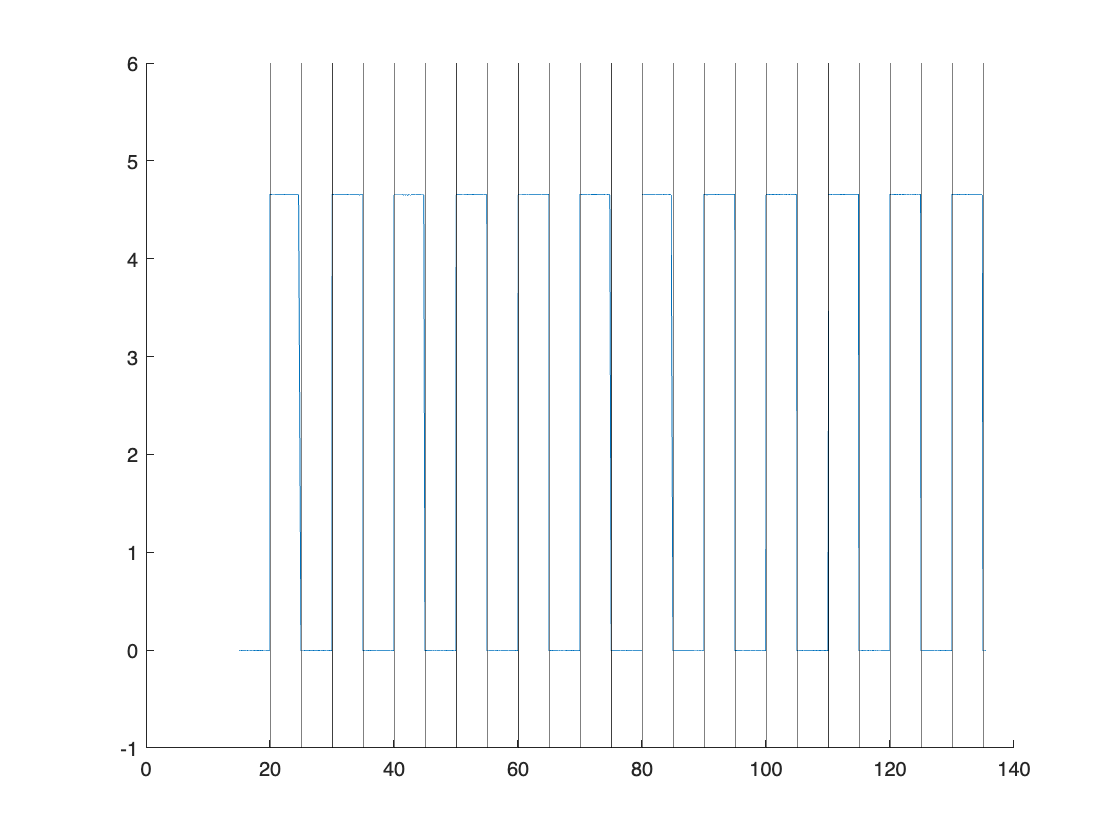

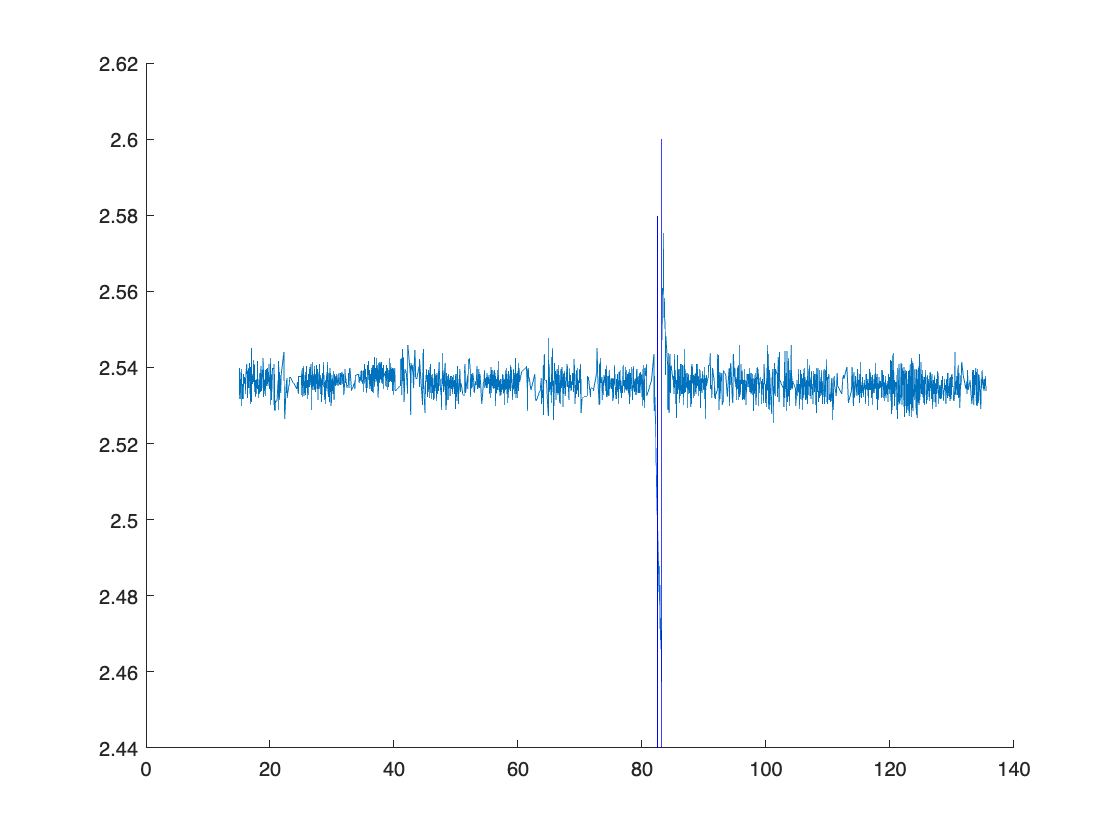

kg2(k).info = KatieMultiLabeler(kg2(k));

kg2(k).info.luz = k_manuallightlabeler(kg2(k));

### for when things get messy...

hifish

tube = 2;
%in = hi;

fishchunk1idx = find(hi(tube).tim < 72.5);
%     
        for j = 1:length(fishchunk1idx)
            hi(tube).pkampchunk1(j) = hi(tube).pkamp(fishchunk1idx(j))/2.3;
            hi(tube).obwampchunk1(j) = hi(tube).obwamp(fishchunk1idx(j))/2.3;
            
            hi(tube).timchunk1(j) = hi(tube).tim(fishchunk1idx(j));

        end

 fishchunk2idx = find(hi(tube).tim >= 72.5);
%     
        for j = 1:length(fishchunk2idx)
            hi(tube).pkampchunk2(j) = hi(tube).pkamp(fishchunk2idx(j))/1.2;
            hi(tube).obwampchunk2(j) = hi(tube).obwamp(fishchunk2idx(j))/1.2;
            
            hi(tube).timchunk2(j) = hi(tube).tim(fishchunk2idx(j));
        end
        

%check
k_fishcalchecker(hi, kg2(k).s,'high frequency fish', tube);

%save calibration
 hi(tube).pkamp = [hi(tube).pkampchunk1, hi(tube).pkampchunk2];
 hi(tube).obwamp = [hi(tube).obwampchunk1, hi(tube).obwampchunk2];
 hi(tube).tim = [hi(tube).timchunk1, hi(tube).timchunk2];

lowfish

tube = 2;
%in = hi;

fishchunk1idx = find(lo(tube).tim < 72.5);
%     
        for j = 1:length(fishchunk1idx)
            lo(tube).pkampchunk1(j) = lo(tube).pkamp(fishchunk1idx(j))/2.3;
            lo(tube).obwampchunk1(j) = lo(tube).obwamp(fishchunk1idx(j))/2.3;
            
            lo(tube).timchunk1(j) = lo(tube).tim(fishchunk1idx(j));

        end

 fishchunk2idx = find(lo(tube).tim >= 72.5);
%     
        for j = 1:length(fishchunk2idx)
            lo(tube).pkampchunk2(j) = lo(tube).pkamp(fishchunk2idx(j))/1.2;
            lo(tube).obwampchunk2(j) = lo(tube).obwamp(fishchunk2idx(j))/1.2;
            
            lo(tube).timchunk2(j) = lo(tube).tim(fishchunk2idx(j));
        end
        

%check
k_fishcalchecker(lo, kg2(k).s,'low frequency fish', tube);

%save calibration
 lo(tube).pkamp = [lo(tube).pkampchunk1, lo(tube).pkampchunk2];
 lo(tube).obwamp = [lo(tube).obwampchunk1, lo(tube).obwampchunk2];
 hi(tube).tim = [lo(tube).timchunk1, lo(tube).timchunk2];